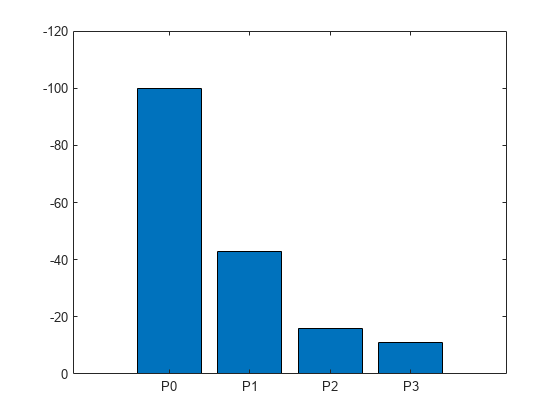

s = serialport("COM20", 115200);
s.configureTerminator("LF");

i = 0;
numReadouts = 100;
x = ["P0" "P1" "P2" "P3"];
a = [0 0 0 0];

figure(1)
while true %i < numReadouts
    splitLineArr = strings(4,6);
    line = readline(s);
    identifier = split(line,':');
    while identifier(2) ~= "1, total_sub"
        line = readline(s);
        identifier = split(line,':');
    end
    splitLineIdx = 1;
    line = readline(s);
    identifier = split(line,':');
    while identifier(2) ~= "0, total_sub"
        splitLineArr(splitLineIdx,:) = split(line,':');
        splitLineIdx = splitLineIdx + 1;
        line = readline(s);
        identifier = split(line,':');
    end


    rssiArr = zeros(1,4);

    for rssiCounter = [1 2 3 4]
        slotTemp = split(splitLineArr(rssiCounter,4),',');
        slot = str2double(slotTemp(1)) + 1;
        if isnan(slot)
            break;
        end
        rssiTemp = split(splitLineArr(rssiCounter,3),' ');
        rssiArr(slot) = str2double(rssiTemp(1));
    end

%     rssiTemp = split(splitLineArr(1,3),' ');
%     slotTemp = split(splitLineArr(1,4),' ');
%     slot = str2double(slotTemp(1)) + 1;
%     rssiArr(slot) = str2double(rssiTemp(1));
%     rssiTemp = split(splitLineArr(2,3),' ');
%     slotTemp = split(splitLineArr(2,4),' ');
%     slot = str2double(slotTemp(1)) + 1;
%     rssiArr(slot) = str2double(rssiTemp(1));
%     rssiTemp = split(splitLineArr(3,3),' ');
%     slotTemp = split(splitLineArr(3,4),' ');
%     slot = str2double(slotTemp(1)) + 1;
%     rssiArr(slot) = str2double(rssiTemp(1));
%     rssiTemp = split(splitLineArr(4,3),' ');
%     slotTemp = split(splitLineArr(4,4),' ');
%     slot = str2double(slotTemp(1)) + 1;
%     rssiArr(slot) = str2double(rssiTemp(1));

    bar(rssiArr);
    set(gca,'XTickLabel',x)
    ylim([-120 0])
    axis ij

    i = i + 1;
end


clear s